clear all
close all

load SintomiLombardia



tempi=SintomiLombardia{:,1}; %date
D=SintomiLombardia{:,2}; %n. infezioni diagnosticate
S1=SintomiLombardia{:,3}; %n. infezioni per inizio sintomi - ISS 7/5/2020
S2=SintomiLombardia{:,4}; %n. infezioni per inizio sintomi - ISS 26/5/2020


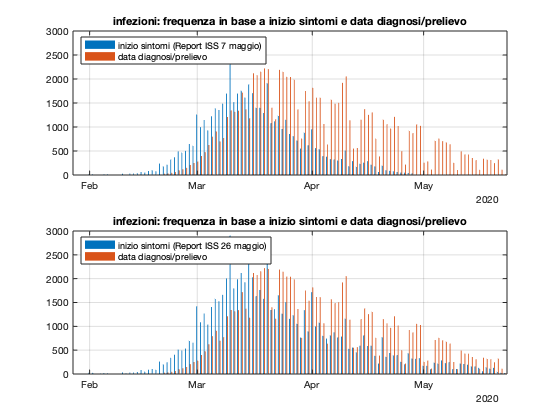

%visualizzazione dei dati come da grafici ISS
figure(1)

subplot(2,1,1)
bar(tempi,[S1 D])
grid
title('infezioni: frequenza in base a inizio sintomi e data diagnosi/prelievo')
legend({'inizio sintomi (Report ISS 7 maggio)','data diagnosi/prelievo'},'Location', 'Northwest')

subplot(2,1,2)
bar(tempi,[S2 D])
grid
title('infezioni: frequenza in base a inizio sintomi e data diagnosi/prelievo')
legend({'inizio sintomi (Report ISS 26 maggio)','data diagnosi/prelievo'},'Location', 'Northwest')

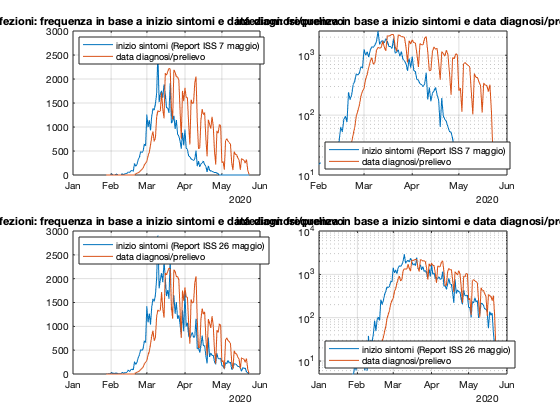



% visualizzazione come 'line plot'

figure(2)

subplot(2,2,1)
plot(tempi,[S1 D])
grid
title('infezioni: frequenza in base a inizio sintomi e data diagnosi/prelievo')
legend({'inizio sintomi (Report ISS 7 maggio)','data diagnosi/prelievo'},'Location', 'Northwest')

subplot(2,2,3)
plot(tempi,[S2 D])
grid
title('infezioni: frequenza in base a inizio sintomi e data diagnosi/prelievo')
legend({'inizio sintomi (Report ISS 26 maggio)','data diagnosi/prelievo'},'Location', 'Northwest')

subplot(2,2,2)
semilogy(tempi,[S1 D])
grid
title('infezioni: frequenza in base a inizio sintomi e data diagnosi/prelievo')
legend({'inizio sintomi (Report ISS 7 maggio)','data diagnosi/prelievo'},'Location', 'Southwest')

subplot(2,2,4)
semilogy(tempi,[S2 D])
grid
title('infezioni: frequenza in base a inizio sintomi e data diagnosi/prelievo')
legend({'inizio sintomi (Report ISS 26 maggio)','data diagnosi/prelievo'},'Location', 'Southwest')

% Cosa è stato aggiunto nel secondo report?
% Il primo report arriva fino al 28 aprile che è il 92-mo dato

%apr28 = datenum('2020,4,28')-inizio -giorno0 +1;
apr28=92;

n_sintomi1 = sum(S1(1:apr28))

n_sintomi1 = 5.1936e+04


n_sintomi2 = sum(S2(1:apr28))

n_sintomi2 = 72162


Increm_perc=100*(n_sintomi2-n_sintomi1)/n_sintomi1

Increm_perc = 38.9446


% Conclusione: dal primo al secondo report il numero di infezioni corredate di data inizio sintomi è
% aumentato del 39%

% Contiamo i casi diagnosticati fino a 10 giorni (ritardo medio) dopo il 28 aprile

n_diagnosi= sum(D(1:apr28+10))

n_diagnosi = 8.2475e+04


% Come è cambiata la capacità di monitoraggio?

Perc_s1_su_D=100*n_sintomi1/n_diagnosi

Perc_s1_su_D = 62.9715


Perc_s2_su_D=100*n_sintomi2/n_diagnosi

Perc_s2_su_D = 87.4956


% Conclusione: nel secondo report la % di casi con data inizio sintomi è
% passata da 63% a 87%


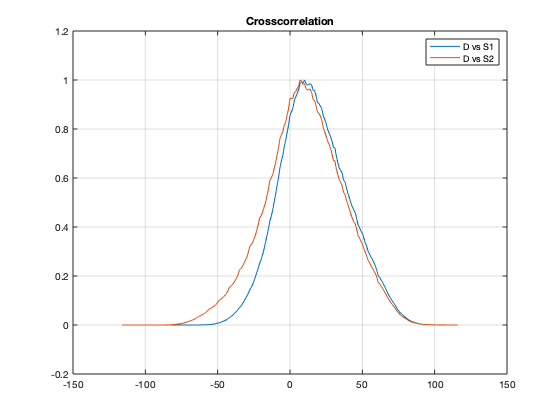

% stimiamo il ritardo tra sintomi e diagnosi


[c1,lags] = xcorr(D,S1);
[c2,lags] = xcorr(D,S2);


figure(3)
plot(lags,c1/max(c1),lags,c2/max(c2)), grid
ax=axis; axis([ax(1) ax(2) -0.2 1.2])
title('Crosscorrelation')
legend({'D vs S1','D vs S2'})


%Conclusione: diagnosi da 7 a 10 giorni dopo i sintomi

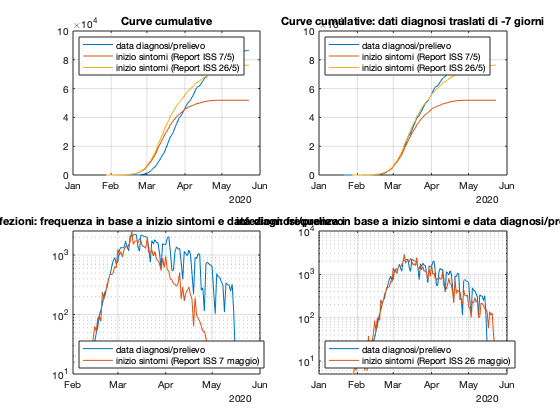

% guardiamo anche il cumulativo

sumD=cumsum(D);
sumS1=cumsum(S1);
sumS2=cumsum(S2);

figure(4)

subplot(221)

plot(tempi,sumD,tempi,sumS1,tempi,sumS2)
grid
title('Curve cumulative')
legend({'data diagnosi/prelievo','inizio sintomi (Report ISS 7/5)','inizio sintomi (Report ISS 26/5)'},'Location', 'Northwest')

subplot(222)

plot(tempi-7,sumD,tempi,sumS1,tempi,sumS2)
grid
title('Curve cumulative: dati diagnosi traslati di -7 giorni')
legend({'data diagnosi/prelievo','inizio sintomi (Report ISS 7/5)','inizio sintomi (Report ISS 26/5)'},'Location', 'Northwest')

subplot(2,2,3)
semilogy(tempi-7, D,tempi,S1)
grid
title('infezioni: frequenza in base a inizio sintomi e data diagnosi/prelievo')
legend({'data diagnosi/prelievo','inizio sintomi (Report ISS 7 maggio)'},'Location', 'Southwest')

subplot(2,2,4)
semilogy( tempi-7, D,tempi,S2)
grid
title('infezioni: frequenza in base a inizio sintomi e data diagnosi/prelievo')
legend({'data diagnosi/prelievo','inizio sintomi (Report ISS 26 maggio)'},'Location', 'Southwest')

%finestra di analisi

giorno0=datenum(SintomiLombardia{1,1})-1;
inizio=datenum('2020,1,28')-giorno0;
%inizio=datenum('2020,4,1')-giorno0;
fine=datenum('2020,5,23')-giorno0;
%fine=datenum('2020,3,30')-giorno0;

tempi=SintomiLombardia{inizio:fine,1}; %date
D=SintomiLombardia{inizio:fine,2}; %n. infezioni diagnosticate
S1=SintomiLombardia{inizio:fine,3}; %n. infezioni per inizio sintomi - ISS 7/5/2020
S2=SintomiLombardia{inizio:fine,4}; %n. infezioni per inizio sintomi - ISS 26/5/2020

% stimiamo il ritardo tra sintomi e diagnosi nella finestra di analisi


[c1,lags] = xcorr(D,S1);
[c2,lags] = xcorr(D,S2);


figure(5)
plot(lags,c1/max(c1),lags,c2/max(c2)), grid
ax=axis; axis([ax(1) ax(2) -0.2 1.2])
title('Crosscorrelation')
legend({'D vs S1','D vs S2'})

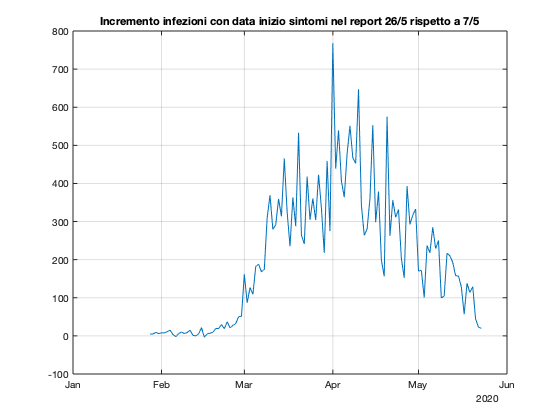


% Guardiamo il profilo degli inizio-sintomi aggiunti 

figure(6)

Delta=S2-S1;
plot(tempi,Delta), grid
title('Incremento infezioni con data inizio sintomi nel report 26/5 rispetto a 7/5')

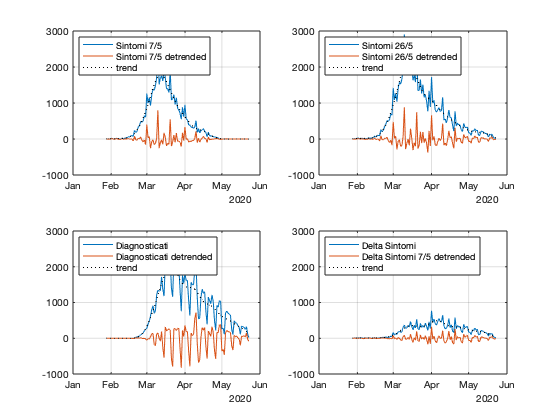

% Analisi spettrale
% Abbiamo a che fare con segnali non stazionari:
% eliminiamo il trend con un filtro
% passa-basso

banda=0.03;
figure(7)

subplot(2,2,1)
x=S1;
L = lowpass(x,banda,1);
LS1=L;
S1d=x-L; %S1 detrended
plot(tempi,x,tempi,x-L,tempi,L,':k'), grid
ylim([-1000 3000])
legend('Sintomi 7/5','Sintomi 7/5 detrended ','trend','Location','northwest') 

subplot(2,2,2)
x=S2;
L = lowpass(x,banda,1);
LS2=L;
S2d=x-L; %S2 detrended
plot(tempi,x,tempi,x-L,tempi,L,':k'), grid
ylim([-1000 3000])
legend('Sintomi 26/5','Sintomi 26/5 detrended ','trend','Location','northwest') 

subplot(2,2,3)
x=D;
L = lowpass(x,banda,1);
LD=L;
Dd=x-L; %D detrended
plot(tempi,x,tempi,x-L,tempi,L,':k'), grid
ylim([-1000 3000])
legend('Diagnosticati','Diagnosticati detrended ','trend','Location','northwest') 

subplot(2,2,4)
x=Delta;
LDelta=L;
L = lowpass(x,banda,1);
Deltad=x-L; %Delta detrended
plot(tempi,x,tempi,x-L,tempi,L,':k'), grid
ylim([-1000 3000])
legend('Delta Sintomi','Delta Sintomi 7/5 detrended ','trend','Location','northwest') 


figure(8)

subplot(1,2,1)
semilogy(tempi,LS1, tempi-7, LD)
grid
title('dati diagnosi traslati di -7 giorni')

legend({'inizio sintomi (Report ISS 7 maggio)','data diagnosi/prelievo'},'Location', 'Southwest')

subplot(1,2,2)
semilogy(tempi,LS2, tempi-7, LD)
grid
title('dati diagnosi traslati di -7 giorni')

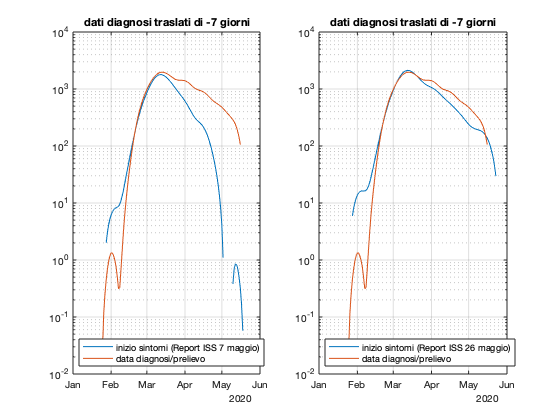

legend({'inizio sintomi (Report ISS 26 maggio)','data diagnosi/prelievo'},'Location', 'Southwest')

% Analisi spettrale

figure(9)

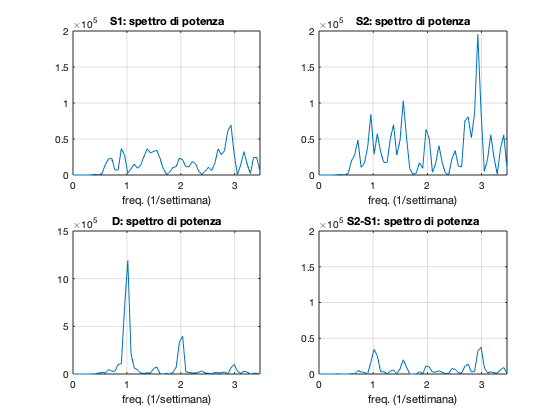



fs=7; % frequenza di campionamento usando la settimana come unità di misura
n = length(S1d);     % number of samples
f = (0:n-1)*(fs/n); % frequency range

subplot(2,2,1)
y=fft(S1d);
power = abs(y).^2/n;    % periodogramma
plot(f,power), grid
axis([f(1) f(ceil(n/2)) 0 2e5])
title('S1: spettro di potenza')
xlabel('freq. (1/settimana)')

subplot(2,2,2)
y=fft(S2d);
power = abs(y).^2/n;    % periodogramma
plot(f,power), grid
axis([f(1) f(ceil(n/2)) 0 2e5])
title('S2: spettro di potenza')
xlabel('freq. (1/settimana)')

subplot(2,2,3)
y=fft(Dd);
power = abs(y).^2/n;    % periodogramma
plot(f,power), grid
axis([f(1) f(ceil(n/2)) 0 15e5])
title('D: spettro di potenza')
xlabel('freq. (1/settimana)')

subplot(2,2,4)
y=fft(Deltad);
power = abs(y).^2/n;    % periodogramma
plot(f,power), grid
axis([f(1) f(ceil(n/2)) 0 2e5])
title('S2-S1: spettro di potenza')
xlabel('freq. (1/settimana)')

%identifichiamo il modello da D a Delta

%z=iddata(Deltad, [Dd S1d],'TimeUnit','day');
%z=iddata(Deltad, Dd,'TimeUnit','day');
z=iddata(Delta, D,'TimeUnit','day');;

%sys=arx(z,[0 [1 1] [0 0]])
%sys=arx(z,[0 1 0])

NN = struc(0,1:1,0);
%NN = struc(0,1:1,1:1,0:8,1:8);

V = arxstruc(z,z,NN);

order = selstruc(V,'mdl')

order =      0     1     0



sys=arx(z,order)


sys =
Discrete-time FIR model: y(t) =  B(z)u(t) + e(t)
  B(z) = 0.2494                                 
                                                
  
Parameterization:
   Polynomial orders:   nb=1   nk=0
   Number of free coefficients: 1
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                     
Estimated using ARX on time domain data "z".
Fit to estimation data: 44.84%              
FPE: 9300, MSE: 9143                        



getcov(sys)

ans = 8.3893e-04

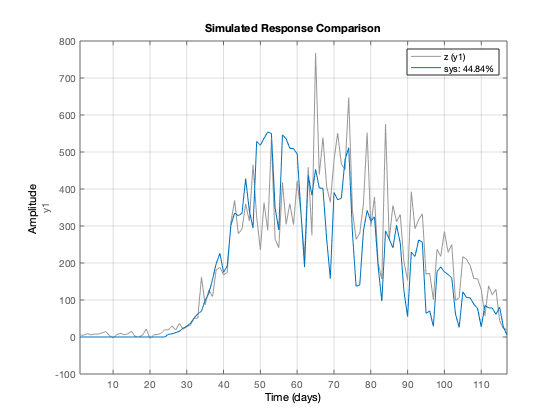


% fit
figure(13)
compare(z,sys,Inf),grid

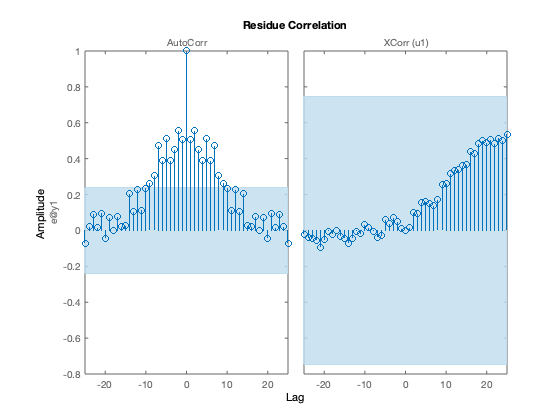


% diagnostica sui residui
figure(14)

resid(z,sys)

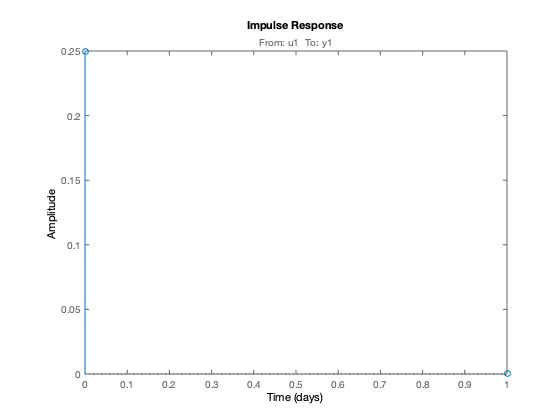

% risposta impulsiva
figure(15)

impulse(sys)

%identifichiamo il modello da S2 a D


z=iddata(LD, LS2,'TimeUnit','day');;


NN = struc(0:0,1:1,0:14);

V = arxstruc(z,z,NN);

order = selstruc(V,'mdl')

order =      0     1     8



sys=arx(z,order)


sys =
Discrete-time FIR model: y(t) =  B(z)u(t) + e(t)
  B(z) = 1.057 z^-8                             
                                                
Sample time: 1 days
  
Parameterization:
   Polynomial orders:   nb=1   nk=8
   Number of free coefficients: 1
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                     
Estimated using ARX on time domain data "z".
Fit to estimation data: 76.21%              
FPE: 2.418e+04, MSE: 2.337e+04              



getcov(sys)

ans = 0.0552

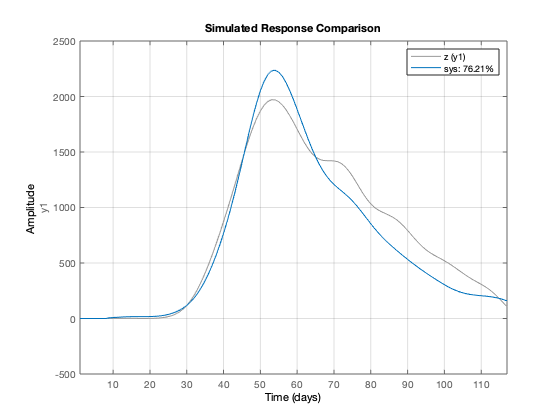


% fit
figure(10)
compare(z,sys,Inf),grid

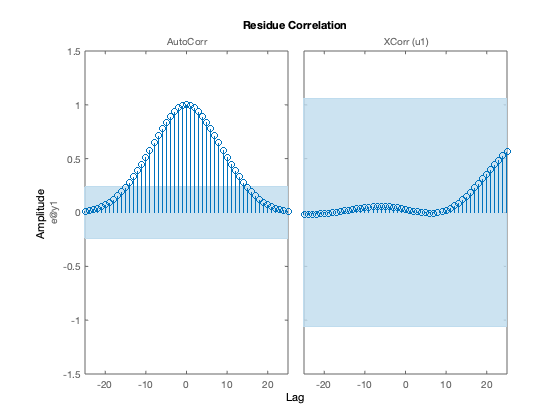


% diagnostica sui residui
figure(11)

resid(z,sys)

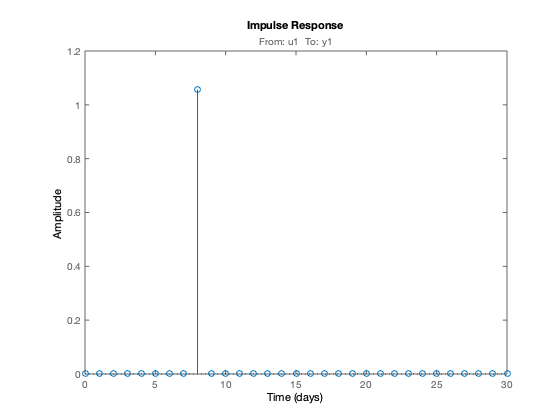


% risposta impulsiva
figure(12)

impulse(sys)